clc;
clear all;
close all;
t=0:0.001:1

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


am=2

am = 2

ac=1

ac = 1

fm=10

fm = 10

fc=100

fc = 100

k=am/ac

k = 2

mt=am*sin(2*pi*fm*t)

mt =          0    0.1256    0.2507    0.3748    0.4974    0.6180    0.7362    0.8516    0.9635    1.0717    1.1756    1.2748    1.3691    1.4579    1.5410    1.6180    1.6887    1.7526    1.8097    1.8596    1.9021    1.9372    1.9646    1.9842    1.9961    2.0000    1.9961    1.9842    1.9646    1.9372    1.9021    1.8596    1.8097    1.7526    1.6887    1.6180    1.5410    1.4579    1.3691    1.2748    1.1756    1.0717    0.9635    0.8516    0.7362    0.6180    0.4974    0.3748    0.2507    0.1256


ct=ac*sin(2*pi*fc*t)

ct =          0    0.5878    0.9511    0.9511    0.5878    0.0000   -0.5878   -0.9511   -0.9511   -0.5878   -0.0000    0.5878    0.9511    0.9511    0.5878    0.0000   -0.5878   -0.9511   -0.9511   -0.5878   -0.0000    0.5878    0.9511    0.9511    0.5878   -0.0000   -0.5878   -0.9511   -0.9511   -0.5878   -0.0000    0.5878    0.9511    0.9511    0.5878   -0.0000   -0.5878   -0.9511   -0.9511   -0.5878   -0.0000    0.5878    0.9511    0.9511    0.5878    0.0000   -0.5878   -0.9511   -0.9511   -0.5878


s=(1+k*mt).*ct

s =          0    0.7354    1.4279    1.6639    1.1725    0.0000   -1.4533   -2.5708   -2.7838   -1.8476   -0.0000    2.0865    3.5552    3.7242    2.3994    0.0000   -2.5729   -4.2847   -4.3932   -2.7738   -0.0000    2.8651    4.6879    4.7253    2.9343   -0.0000   -2.9343   -4.7253   -4.6879   -2.8651   -0.0000    2.7738    4.3932    4.2847    2.5729   -0.0000   -2.3994   -3.7242   -3.5552   -2.0865   -0.0000    1.8476    2.7838    2.5708    1.4533    0.0000   -1.1725   -1.6639   -1.4279   -0.7354


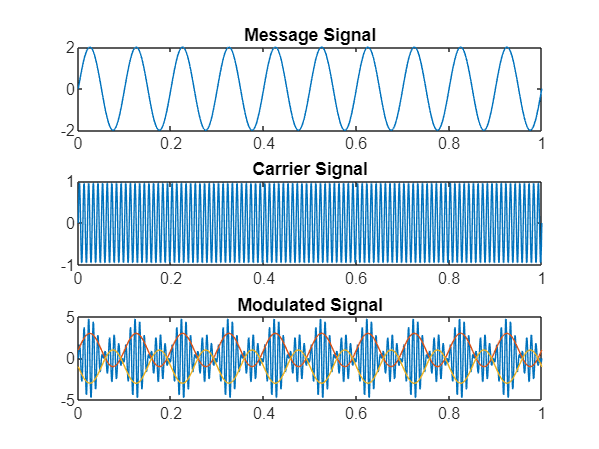

subplot(3,1,1)
plot(t,mt)
title("Message Signal")
subplot(3,1,2)
plot(t,ct)
title("Carrier Signal")
subplot(3,1,3)
plot(t,s,t,ac+mt,t,-ac-mt)
title("Modulated Signal")